## Energy band diagram and block charge diagram

% Constants
k = 1.380649e-23; % Boltzmann constant (J/K)
T = 300; % Temperature in Kelvin
q = 1.602176634e-19; % Elementary charge (C)
V_T = k * T / q; % Thermal voltage (V)


### Given phi_F and phi_S for conditions (a) to (e) in units of kT/q

phi_F_values = [18, -12, 12, -15, 9];
phi_S_values = [9, 0, 24, 3, 21];


### Energy levels (arbitrary units for visualization)

E_g = 1.1; % Bandgap of silicon (eV)

% Create figure for subplots
figure;

### Calculate the Fermi level and surface potential in volts

for i = 1:length(phi_F_values)
    phi_F = phi_F_values(i) * V_T;
    phi_S = phi_S_values(i) * V_T;
    
    % Energy band levels
    E_f = -phi_F; % Fermi level below vacuum level
    E_c = E_f + 0.3; % Conduction band edge above Fermi level
    E_v = E_c - E_g; % Valence band edge below conduction band edge
    

####     Energy band diagram subplot

    subplot(5, 2, 2*i-1);
    hold on;
    plot([0, 1], [E_c, E_c], 'r', 'LineWidth', 2);
    plot([0, 1], [E_v, E_v], 'b', 'LineWidth', 2);
    plot([0, 1], [E_f, E_f], 'k--', 'LineWidth', 2);
    title(sprintf('Energy Band Diagram (%c)', 'a'+i-1));
    xlabel('Position');
    ylabel('Energy (eV)');
    legend('Conduction Band', 'Valence Band', 'Fermi Level', 'Location', 'BestOutside');
    ylim([E_v-0.5, E_c+0.5]);
    hold off;
    

####     Block charge diagram subplot

    subplot(5, 2, 2*i);
    hold on;
    % Depending on the condition, show the charge at the surface
    if phi_F_values(i) > phi_S_values(i) % Accumulation
        patch([0.4 0.6 0.6 0.4], [-1 -1 0 0], 'b');
        text(0.5, -0.5, 'Accumulation', 'HorizontalAlignment', 'center');
    elseif phi_S_values(i) == 0 % Flat-band
        text(0.5, 0, 'Flat-band', 'HorizontalAlignment', 'center');
    elseif phi_S_values(i) > 2*phi_F_values(i) % Strong inversion
        patch([0.4 0.6 0.6 0.4], [0 0 1 1], 'r');
        text(0.5, 0.5, 'Strong Inversion', 'HorizontalAlignment', 'center');
    else % Depletion or weak inversion
        patch([0.4 0.6 0.6 0.4], [0 0 0.5 0.5], 'r');
        if phi_F_values(i) + phi_S_values(i) < 0
            text(0.5, 0.25, 'Depletion', 'HorizontalAlignment', 'center');
        else
            text(0.5, 0.25, 'Weak Inversion', 'HorizontalAlignment', 'center');
        end
    end
    title(sprintf('Block Charge Diagram (%c)', 'a'+i-1));
    xlabel('Position');
    ylabel('Charge Density');
    xlim([0, 1]);
    ylim([-1, 1]);
    hold off;
end

### Adjust layout

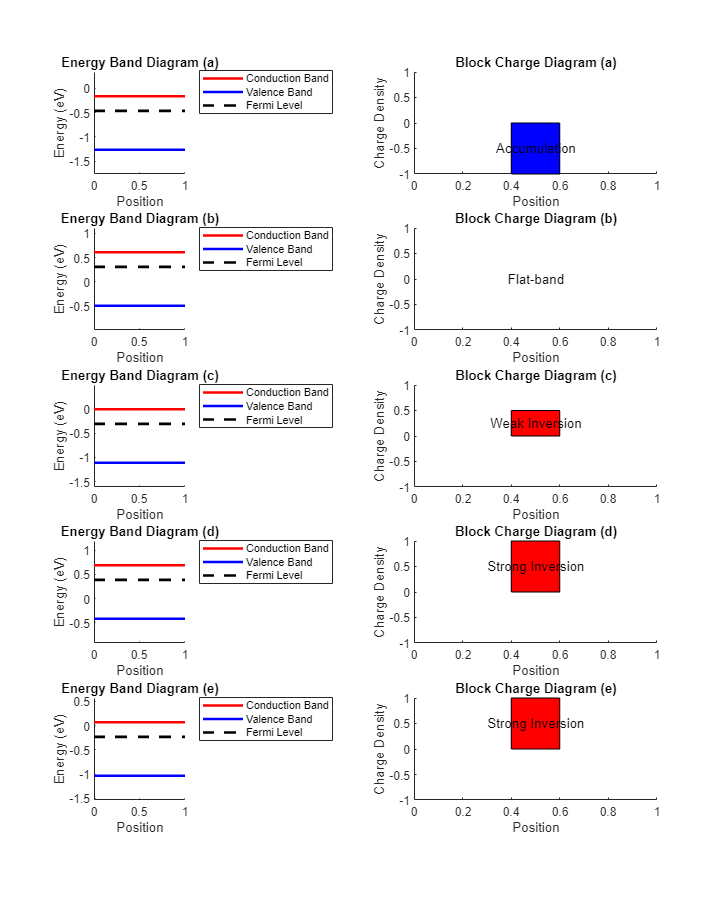

set(gcf, 'Position', [100, 100, 800, 1000]); % Set figure position and size